## МИУ СFIE

Программа E-поляризация МВИ для цилиндра эллиптического сечения

02_03_21

close all;
clear variables;

#### Входные данные 

% Пример использования:
a = 2;
b = 1;
phi_grad = 60;
N= 400;
alpha = 0.5;
etta = 120*pi;

#### Генерация EFIE с помощью класса

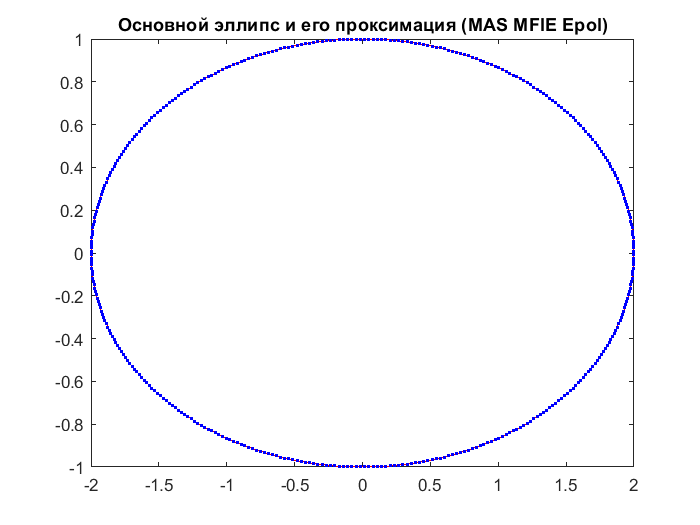

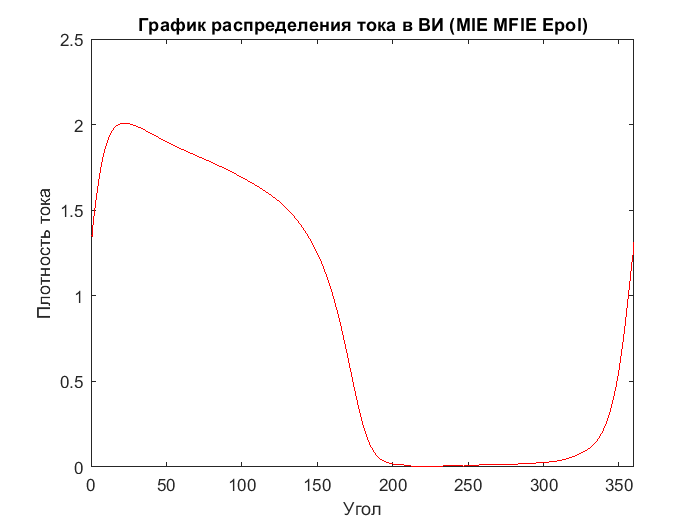

calc_1 = class_MIE_EFIE_ellips_E_pol(a,b,phi_grad);
calc_1.calculate_main_ellips(N);
calc_1.calculate_I(N);

EFIE_Zmn = calc_1.Zmn;
EFIE_Ei = calc_1.Ei;
EFIE_I = EFIE_Zmn\EFIE_Ei;


#### Генерация MFIE с помощью класса

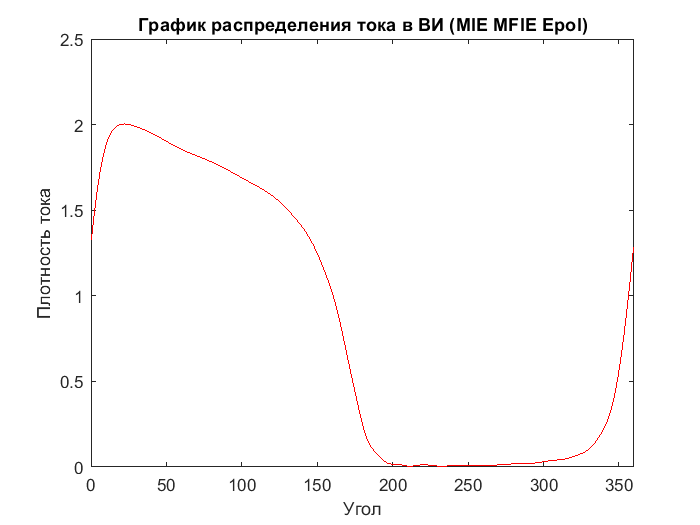

calc_2 = class_MIE_MFIE_E_pol(a,b,phi_grad);
calc_2.calculate_main_ellips(N);
calc_2.calculate_I(N);

MFIE_Zmn = calc_2.Zmn;
MFIE_Hi = calc_2.Hi;
MFIE_I = MFIE_Zmn\MFIE_Hi;

#### Графики токов (где по оси НОМЕР участка)

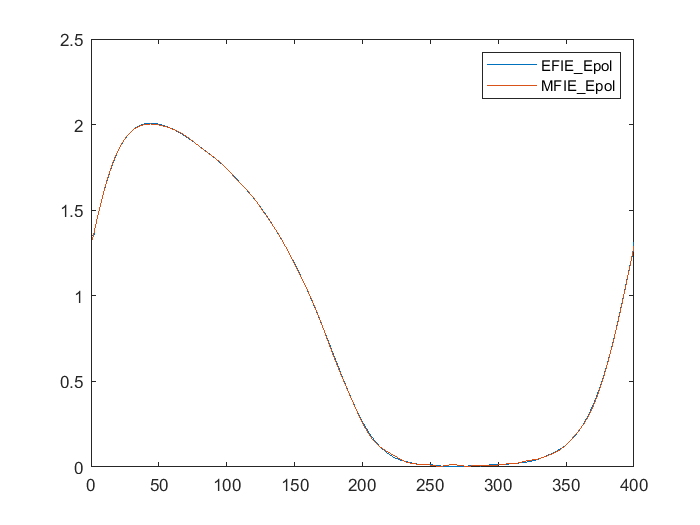

n = 1 : length(EFIE_I);
plot(n, abs(EFIE_I), n, abs(MFIE_I))
legend('EFIE\_Epol', 'MFIE\_Epol')

#### Вычисление CFIE

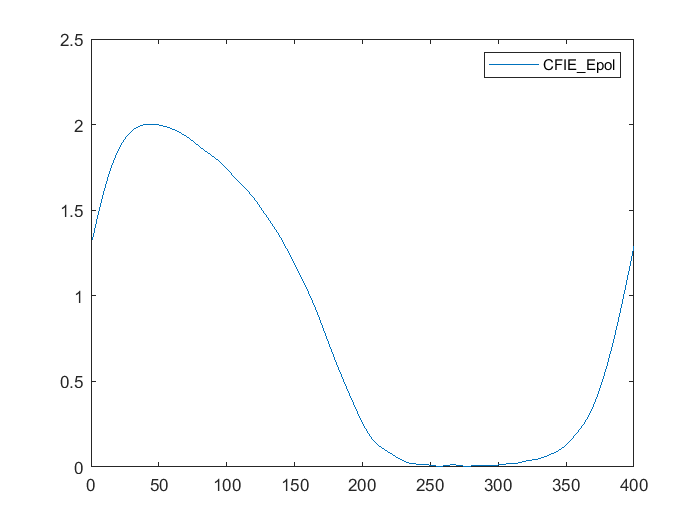

CFIE_Zmn = alpha*EFIE_Zmn + (1-alpha)*etta*MFIE_Zmn;
CFIE_Ei = alpha*EFIE_Ei + (1-alpha)*etta*MFIE_Hi;

CFIE_I = CFIE_Zmn\CFIE_Ei;

plot(n, abs(CFIE_I))
legend('CFIE\_Epol')

#### Построение сравниельных графиков EFIE, MFIE, CFIE для эллипса

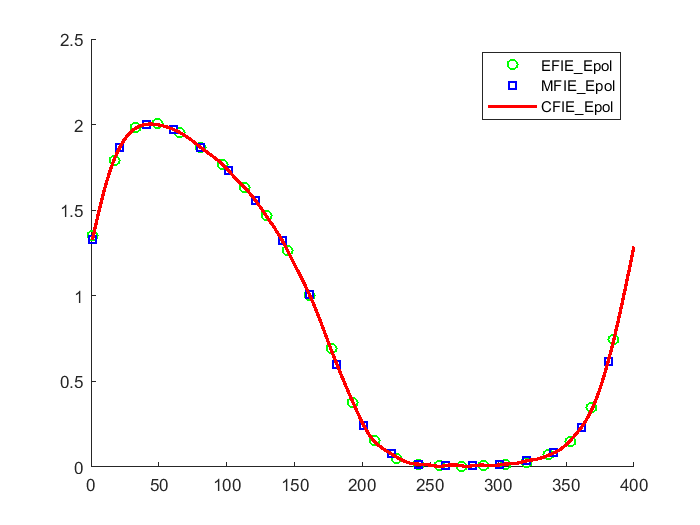

figure;
hold on;
plot(n, abs(EFIE_I),'go', 'MarkerIndices', 1:16:length(n), 'LineWidth', 1, 'DisplayName','EFIE\_Epol')
plot(n, abs(MFIE_I),'bs', 'MarkerIndices', 1:20:length(n),'LineWidth',1, 'DisplayName','MFIE\_Epol')
plot(n, abs(CFIE_I), 'r', 'LineWidth', 2, 'DisplayName','CFIE\_Epol')
legend;
hold off;